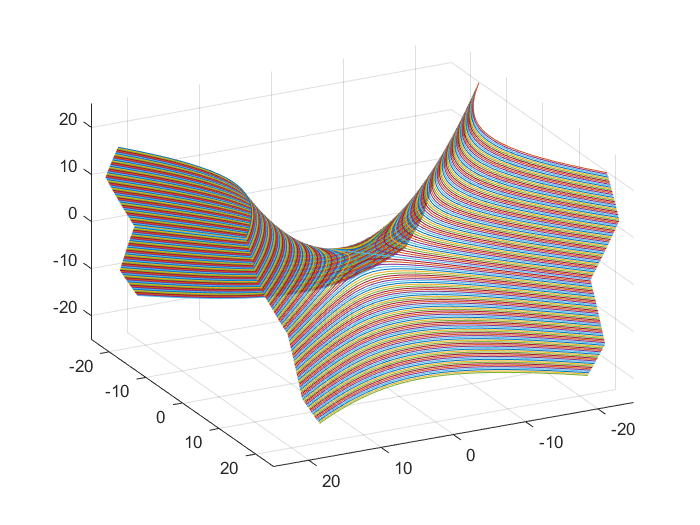

clc
hold on
axis ([-25 25 -25 25 -25 25])
axis on 
grid on
a=4;b=4;
x=-a-17:a+17;
y=-b-17:b+17;
[X,Y]=meshgrid(x,y); 
Z=zeros(size(X))+20;
view([0.3848 0.7627 0.5199])
pic_num = 1;
for i=1:150
Z=Z-1/4; 
if Z(1)>0
h=mesh(X,Y,Z);
Y1=y;
X1=a*sqrt(Z(1)+Y1.^2/b.^2);
Z1=zeros(size(X1))+Z(1);
g=plot3(X1,Y1,Z1,-X1,Y1,Z1);
else
if abs(Z(1))<=0.01
h=surf(X,Y,Z);
y1=(b/a)*x;
y2=-(b/a)*x;
z1=zeros(size(x));
g=plot3(x,y1,z1,x,y2,z1); 
else
h=surf(X,Y,Z); 
X1=x;
Y1=b*sqrt(-Z(1)+X1.^2/a.^2);
Z1=zeros(size(X1))+Z(1);
g=plot3(X1,Y1,Z1,X1,-Y1,Z1);
end 
end
F=getframe(gcf);
I=frame2im(F);
[I,map]=rgb2ind(I,256);%制作动图
if pic_num == 1
    imwrite(I,map,'test6.gif','gif', 'Loopcount',inf,'DelayTime',0.2);
else
    imwrite(I,map,'test6.gif','gif','WriteMode','append','DelayTime',0.2);
end
pic_num = pic_num + 1;
delete(h);
end 